clear; clc; close('all');
%test1
% A = [
%         -125    123.65;
%         123.65  -123
%     ];
% y0 = [
%         1; 
%         1
%      ];
%  
% t0 = 0;
% tn = 0.5; 

%test2
A = [[-100.00000 0.00000000 0.00000000 0.00000000 0.00000000];
[-99.000000 0.00000000 -1.0000000 0.00000000 0.00000000];
[-100.00000  2.0000000 -2.0000000 0.00000000 0.00000000];
[-100.00000  2.0000000  9998.0000 -9990.0000 -10.000000];
[-100.00000  2.0000000  9988.0000  20.000000 -10010.000]];
y0 = [10, 11, 11, 111, 111];
t0 = 0;
tn = 1;

%test3
% A = [[-1, 0, 0, 0, 0, 0];
%      [1, -1, 0, 0, 0, 0];
%      [0, 0, -10000, 0, 0, 0];
%      [0, 0, 1, -10000, 0, 0];
%      [0, 0, 0, 2, -10000, 0];
%      [0, 0, 0, 0, 3, -10000]];
% y0 = [1, 1, 1000, 1000, 1000, 1000];
% t0 = 0;
% tn = 1;


format long;
tic;
[y1, t1, d1] = Richardson("EulerReverse",t0, y0, tn, A);

2001 2.1125 
4001 2.8371 
8001 2.9399 
16001 2.1917 
32001 1.3907 
64001 0.79833 
128001 0.43655 
256001 0.2284 
512001 0.11691 
1024001 0.059155 
2048001 0.029757 
4096001 0.014924 
8192001 0.0074733 


a1=toc;
a1

a1 =   23.723963200000000


d1

d1 =   -0.000000201615951  -0.000000201615824  -0.000000201611610  -0.007473330615956  -0.007465869328409


% h=(t1(2)-t1(1))/2;
% [t, y] = EulerReverse(t0, y0, h, tn, A);
% y
% hold off; 
% loglog(t(1:20:length(t)),y(5,1:20:length(t)))
% xlabel('t')
% ylabel('Y')

tic;
[y2, t2, d2] = Richardson("AdamsExtra2",t0, y0, tn, A);

20001 2.7779 
40001 1.3889 
80001 0.50927 
160001 0.15659 
320001 0.043635 
640001 0.011534 
1280001 0.002966 


a2=toc;
a2

a2 =    4.294368900000000


% h=(t1(2)-t1(1))/2;
% [t, y] = AdamsExtra2(t0, y0, h, tn, A);
% y
% hold off; 
% loglog(t(1:20:length(t)),y(5,1:20:length(t)))
% xlabel('t')
% ylabel('Y')


tic;
[y3, t3, d3] = Richardson("RungeKutta",t0, y0, tn, A);

7195 13.966 
14389 0.4815 
28777 0.016466 
57554 0.00080731 


a3=toc;
a3

a3 =    0.370019300000000


h=(t1(2)-t1(1))/2;
[t, y] = RungeKutta(t0, y0, h, tn, A);
y

y = 	1.0e+02 *

   0.100000000000000   0.099999389650300   0.099998779304326   0.099998168962076   0.099997558623552   0.099996948288753   0.099996337957679   0.099995727630331   0.099995117306707   0.099994506986809   0.099993896670636   0.099993286358188   0.099992676049464   0.099992065744466   0.099991455443193   0.099990845145645   0.099990234851822   0.099989624561723   0.099989014275350   0.099988403992701   0.099987793713778   0.099987183438579   0.099986573167105   0.099985962899356   0.099985352635331   0.099984742375032   0.099984132118457   0.099983521865606   0.099982911616481   0.099982301371080   0.099981691129403   0.099981080891452   0.099980470657224   0.099979860426722   0.099979250199944   0.099978639976890   0.099978029757561   0.099977419541957   0.099976809330077   0.099976199121921   0.099975588917490   0.099974978716783   0.099974368519800   0.099973758326542   0.099973148137008   0.099972537951199   0.099971927769113   0.099971317590752   0.099970707416115   0

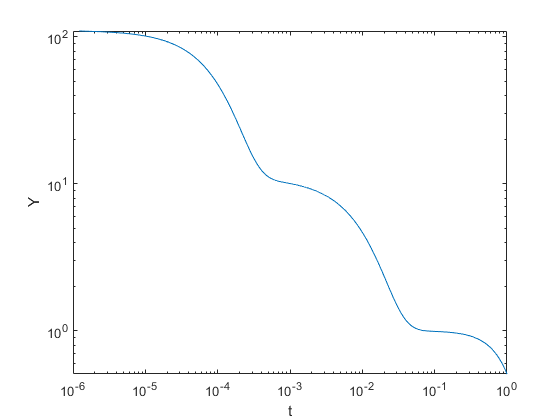

hold off; 
loglog(t(1:20:length(t)),y(5,1:20:length(t)))
xlabel('t')
ylabel('Y')